# Neural networks and tree methods for regression

In this lecture, we'll use shallow neural networks for regression-based problems, and try to benchmark the performance of a shallow neural network against tree-based methods using the age metabolomics dataset.

## Load the dataset

The dataset we'll use is the age metabolomics dataset we have used in the random forest module.

clear all; data = readtable('age_metabolomics.xlsx')

data = 302×444 table
    sex     age      menopause     Carnitine    Betaine    Choline    Dimethyl_glycine    Sarcosine    Trimethyl_amine_N_oxide    Carnitine_1    Octadecenoyl_carnitine    Acetyl_carnitine    Alanine    Arginine    Asparagine    AsparticAcid    Glutamine    Histidine    Isoleucine    Leucine    Lysine    Methionine    Ornithine    Phenyl_alanine    Proline    Serine    Threonine    Tryptophan    Tyrosine    Valine    Creatinine    Kynurenine

Note that the first row is the time point of metabolomics measurement. We won't consider the time dimension in this analysis and we'll remove this row from the dataset. Also, we're not interested in predicting the `sex` of the patient, or if they have `Menopause,` so we'll remove those categorical columns as well.

% Remove the time variable and the categorical variables
data(1, :) = []; data(:, [1, 3]) = [];
X = data;

Let's now create our predictor dataset, which will consist of the metabolomics data ($X$) and try to predict the age of a patient ($Y$). 

% Create our X and Y variables
Y = X(:, 1); X(:, 1) = [];

While decision trees and random forests algorithms can handle missing data, neural network functions cannot handle missing values. Thus, we can either remove the patient row that contains missing values or perform some data imputation. The number of patients is still fairly small, so we'll perform median imputation for all metabolomics values that are missing in the dataset.

% Perform missing data imputation using the median
for i = 1:width(X)
    X.(i)(isnan(X.(i))) = nanmedian(table2array(X(:, i)));
end

We'll split the dataset into training and test data using the `trainTestSplit` function.

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(X, Y, trainingSize, randomstate);

Finally, all of the metabolomics data are positive values. Thus, we'll perform min-max scaling to scale the data, instead of using the z-score.

colmin = min(Xtrain); colmax = max(Xtrain);
Xtrain = rescale(Xtrain, 'InputMin', colmin, 'InputMax', colmax); 
Xtest  = rescale(Xtest,  'InputMin', colmin, 'InputMax', colmax); 
Xtrain = Xtrain'; Ytrain = Ytrain'; Xtest = Xtest'; Ytest = Ytest';

### Linear regression

Note that the number of features is 2x that of the number of patients in the dataset. **This is an underdetermined problem, resulting in model overfitting. Thus it is not an optimal model choice**. However, let's still see what outputs we get when trying to fit the linear regression model to such a dataset.

% Fit an ordinary least squares model
lm = fitlm(Xtrain', Ytrain', 'linear')

lm = Linear regression model:
    y ~ [Linear formula with 442 terms in 441 predictors]

Estimated Coefficients:
                   Estimate     SE    tStat    pValue
                   _________    __    _____    ______

    (Intercept)      -30.525    0     -Inf      NaN  
    x1                6.4154    0      Inf      NaN  
    x2                88.988    0      Inf      NaN  
    x3              -0.75292    0     -Inf      NaN  
    x4                     0    0      NaN      NaN  
    x5               -21.522    0     -Inf      NaN  
    x6               -11.002    0     -Inf      NaN  
    x7               0.51256    0      Inf      NaN  
    x8                     0    0      NaN      NaN  
   

Note that the model has overfit (standard error is 0), and the T-statistics / p-value are either `inf` or `NaN` values based on the sign of the coefficient. Even though we know this is an ill-posed problem, let's still use the linear model as our benchmark for the neural networks and tree-based methods by getting the predictions and Pearson correlation coefficient values. 

% Use linear model to predict age using metabolomics dataset
ypred_lm = predict(lm, Xtest')

ypred_lm =    70.9939
    0.8874
   78.5361
   43.5157
  102.9731
   35.5724
  146.8657
    2.7545
   16.4062
   75.5861


% Compute correlation
r_lm = corr(ypred_lm, Ytest')

r_lm = 0.5727

The Pearson correlation between the linear model predictions and the age in the test set is 0.57. We would expect that other models will beat this value. 

## Using neural networks for regression

### Setup the shallow neural network architecture

We'll setup a **shallow neural network architecture** using the `trainNetwork` function**.** First, we need to set up the network `layers` object with the following architecture:

- `sequenceInputLayer` sets up the data input layer

- `fullyConnectedLayer` constructs a hidden layer. The first argument sets it up with 10 activation nodes. The additional parameters specify how we are going to initialize the weights and biases using small, random values.

- `dropoutLayer` takes the nodes from the previous layer and sets 30% of them to randomly be 0 for this round of forward propagation. This step is a form of regularization and is meant to prevent model overfitting, as discussed in more depth in the optimization lecture.

- `reluLayer` performs a ReLU transformation

- The final `fullyConnectedLayer` is essentially our way of re-mapping the engineered features in the hidden layer back to our response variable size, which is a single vector. 

- The `regressionLayer` is the cost function that computes the mean squared loss. 

snnlayers = [...
    
    sequenceInputLayer(size(Xtrain, 1))           % Input data layer
    
    fullyConnectedLayer(10, ...                   % Hidden layer 1 with 10 activation nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal') 
    
    dropoutLayer(0.3)                             % Randomly and temporarily drop out 30% of the data

    reluLayer                                     % ReLU activation function 
    
    fullyConnectedLayer(size(Ytrain, 1), ...      % Output layer with 1 nodes corresponding to age vector
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal') 
    
    regressionLayer                               % Regression layer
];

#### Setup the shallow neural network hyperparameters

Now let's setup the shallow neural network hyperparameters. A description of each hyperparameter is shown below.

options = trainingOptions(...
    'adam', ...                                   % Adam optimization
    'InitialLearnRate', 0.01, ...                 % Set the initial learning rate to 0.01 
    'MaxEpochs', 1000, ...                        % Maximum number of epochs to train algorithm
    'ValidationData', {Xtest, Ytest}, ...         % Dataset to use as the validation set
    'ValidationFrequency', 100, ...               % Frequency to validate the network at regular intervals
    'Verbose', true, ...                          % Outputs information about training 
    'L2Regularization', 1.0000e-05, ...           % Perform additional Ridge Regularization to constrain the model further
    'Shuffle', 'every-epoch', ...                 % Data shuffling for every epoch
    'Plots', 'training-progress' ...              % Show plots for every epoch
); 

#### Train the neural networks

Now let's train the shallow neural network using the `trainNetwork` function.

Training on single GPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:12 |        50.32 |        50.82 |    1266.0408 |    1291.4021 |          0.0100 |


|      50 |          50 |       00:00:14 |        20.85 |              |     217.2960 |              |          0.0100 |


|     100 |         100 |       00:00:14 |        18.85 |        15.11 |     177.6590 |     114.1882 |          0.0100 |


|     150 |         150 |       00:00:15 |        18.44 |              |     170.0225 |              |          0.0100 |


|     200 |         200 |       00:00:16 |        17.11 |        13.39 |     146.3204 |      89.6694 |          0.0100 |


|     250 |         250 |       00:00:16 |        17.21 |              |     148.0771 |              |          0.0100 |


|     300 |         300 |       00:00:17 |        16.36 |        12.24 |     133.8245 |      74.8691 |          0.0100 |


|     350 |         350 |       00:00:17 |        15.92 |              |     126.7216 |              |          0.0100 |


|     400 |         400 |       00:00:18 |        16.14 |        11.45 |     130.1840 |      65.4964 |          0.0100 |


|     450 |         450 |       00:00:18 |        15.90 |              |     126.3698 |              |          0.0100 |


|     500 |         500 |       00:00:19 |        13.95 |        10.81 |      97.3551 |      58.3765 |          0.0100 |


|     550 |         550 |       00:00:20 |        15.99 |              |     127.7931 |              |          0.0100 |


|     600 |         600 |       00:00:20 |        14.09 |        10.56 |      99.3152 |      55.7313 |          0.0100 |


|     650 |         650 |       00:00:21 |        15.58 |              |     121.4296 |              |          0.0100 |


|     700 |         700 |       00:00:21 |        14.85 |        10.03 |     110.2180 |      50.3248 |          0.0100 |


|     750 |         750 |       00:00:22 |        15.36 |              |     117.9654 |              |          0.0100 |


|     800 |         800 |       00:00:23 |        15.59 |        10.45 |     121.4830 |      54.6437 |          0.0100 |


|     850 |         850 |       00:00:23 |        14.05 |              |      98.7529 |              |          0.0100 |


|     900 |         900 |       00:00:24 |        13.58 |         9.58 |      92.2548 |      45.9301 |          0.0100 |


|     950 |         950 |       00:00:24 |        13.20 |              |      87.0883 |              |          0.0100 |


|    1000 |        1000 |       00:00:25 |        13.51 |         9.75 |      91.2898 |      47.5731 |          0.0100 |


|======================================================================================================================|


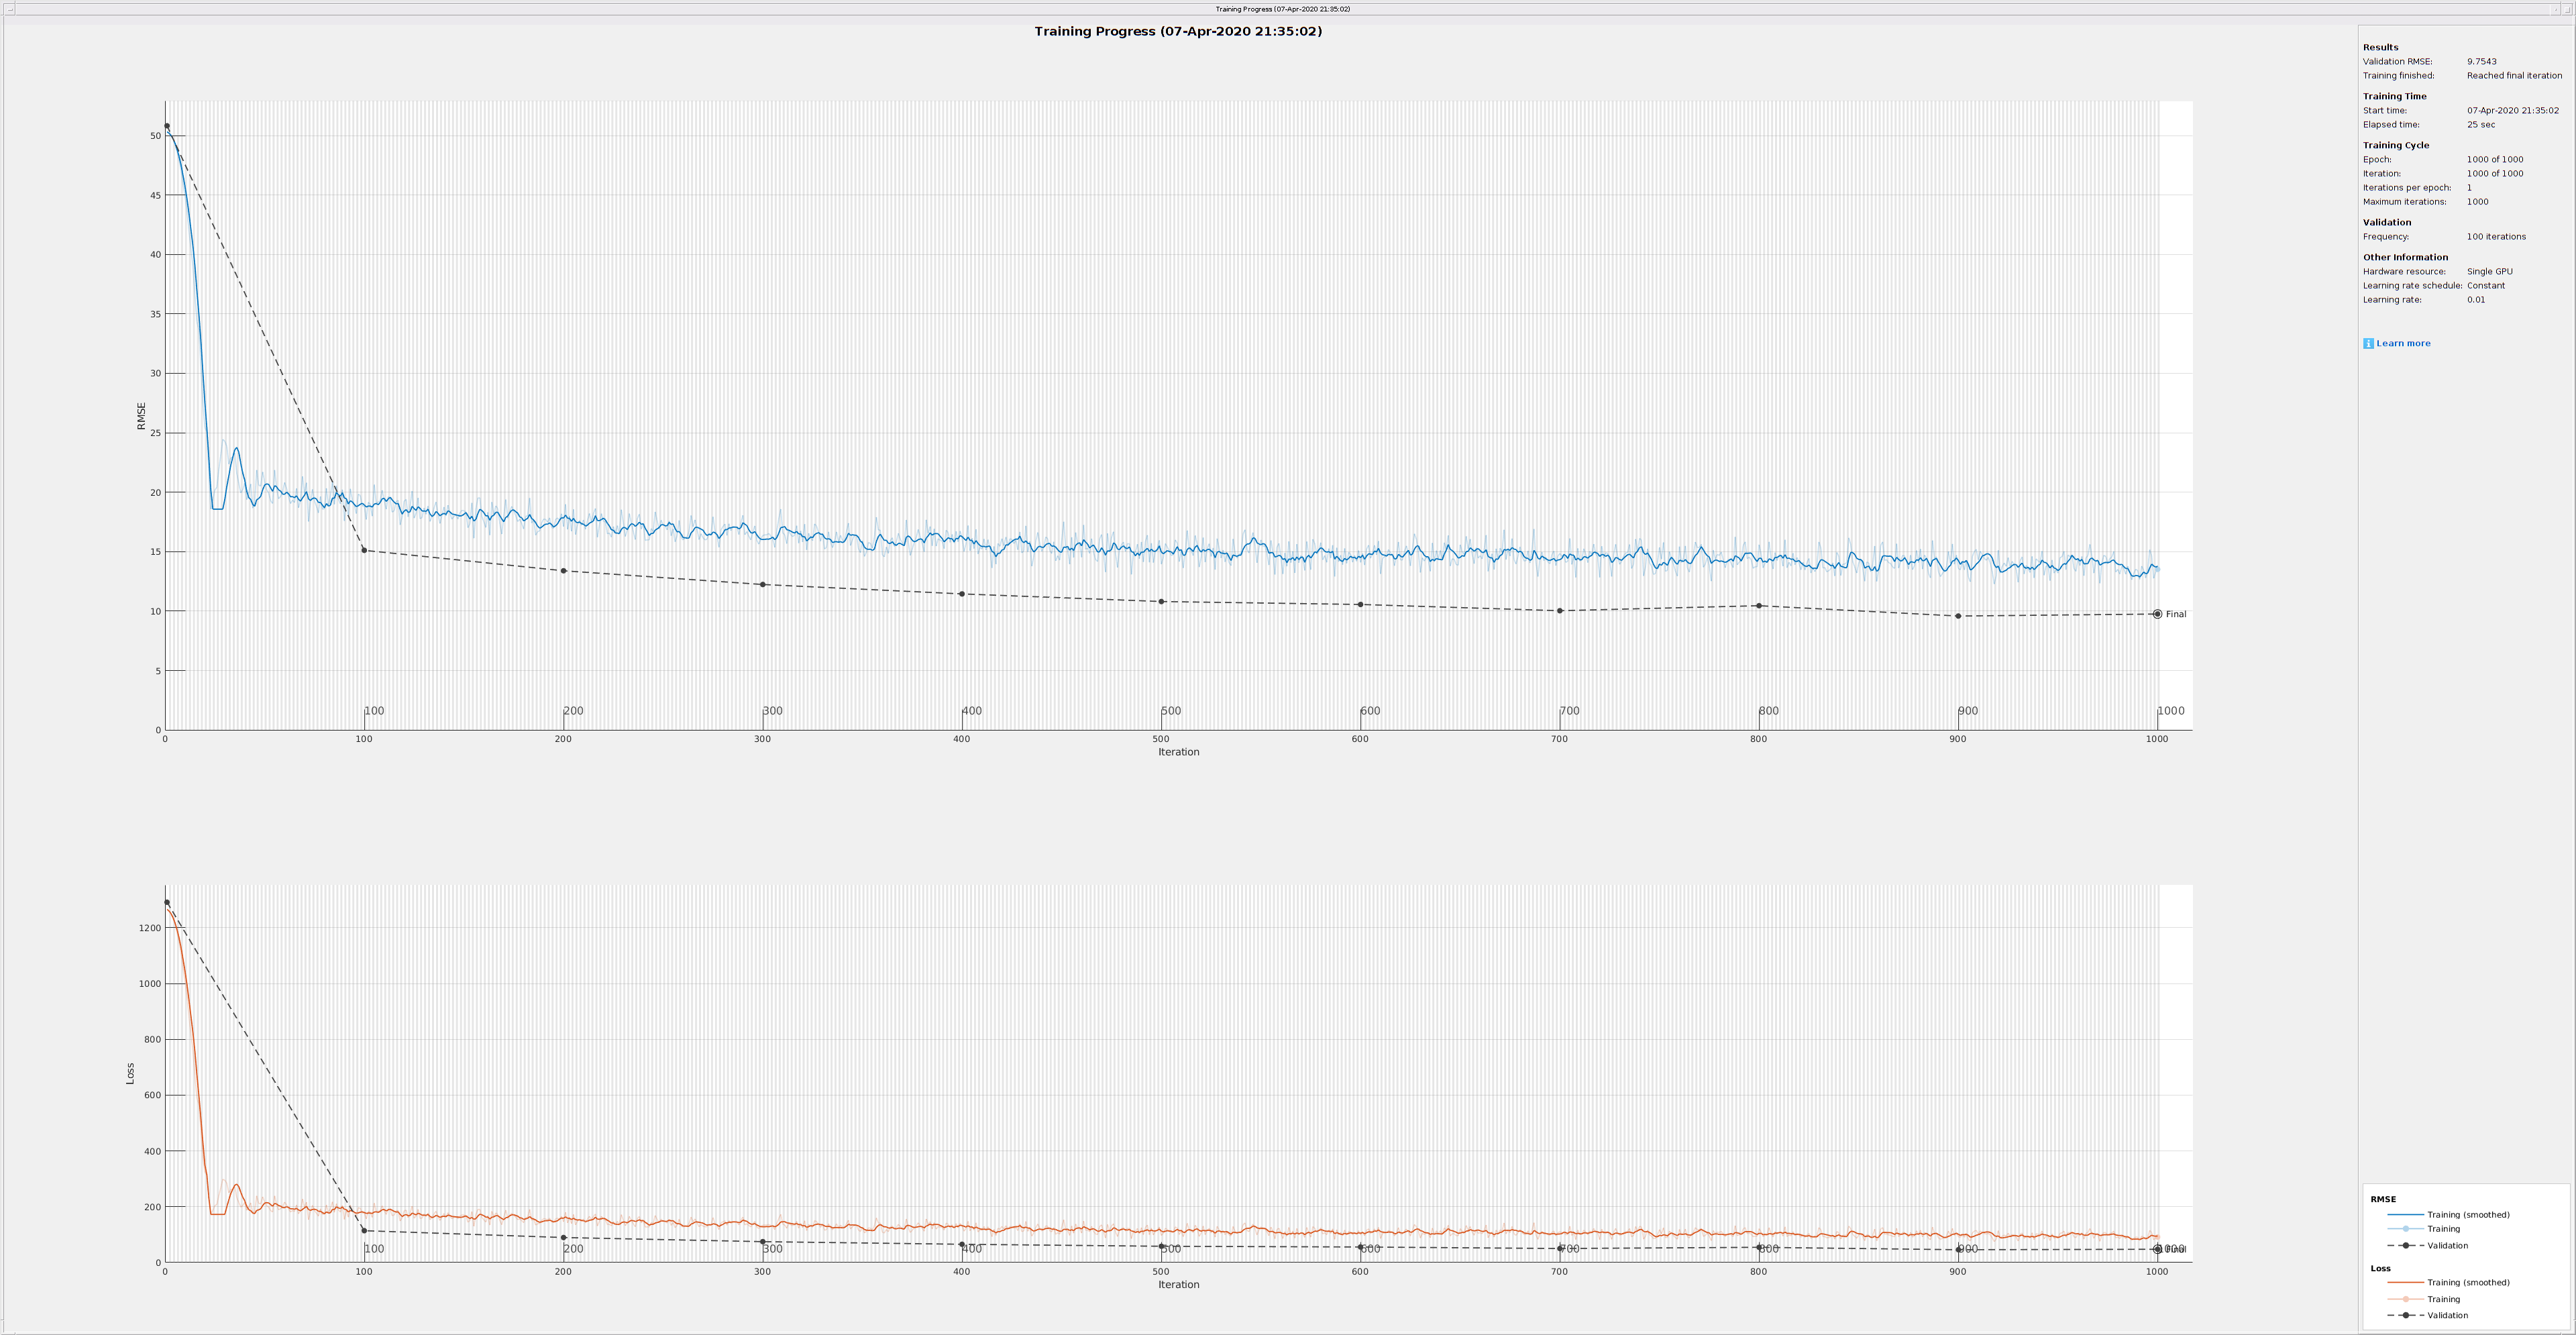

snn =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'regressionoutput'}


[snn, ~] = trainNetwork(Xtrain, Ytrain, snnlayers, options)

#### Make predictions using the trained neural networks

ypred_snn = predict(snn, Xtest)

ypred_snn = 1×61 single row vector
   23.9807   53.9583   52.0498   47.8727   79.0200   63.1899   81.9760   22.4156   22.5739   36.6711   66.8701   51.5234   38.1619   48.5362   27.4082   34.2729   37.2920   56.7801   62.7243   56.3734   55.9465   28.5518   64.8187   67.1260   54.4186   28.3735   46.6959   70.8658   36.2298   56.8343   74.9356   61.9315   54.4406   51.2706   58.6733   53.8191   60.7055   55.5096   35.7656   30.1365   43.5887   39.6772   44.3230   60.3320   40.5200   45.2538   34.0695   29.5609   30.2778   34.7507


#### Correlation analysis between the test age values and the predicted age values

Let's compute the Pearson correlation coefficient between the test age variable and the predicted values from the neural net.

r_snn = corr(Ytest', ypred_snn')

r_snn = single
0.8640

It looks like the shallow neural net is a better model for the age metabolomics dataset compared to the overfitted ordinary least squares model. Let's now benchmark the dataset against tree-based algorithms to see if they can perform better..

### Tree-based models

We'll use the same dataset for training the neural networks to train decision trees and random forests. 

#### Decision trees

First let's train some decision trees and perform some hyperparameter optimization to get the best result. Then we'll use the decision tree to perform a regression on the test dataset to output predicted values. Finally, we'll compute the correlation between the test set and the predicted age values.

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      5.3009 |      0.6096 |      5.3009 |      5.3009 |           15 |


|    2 | Accept |      5.3101 |     0.12483 |      5.3009 |      5.3018 |           70 |


|    3 | Accept |      5.4757 |    0.077663 |      5.3009 |      5.3009 |            1 |


|    4 | Accept |       5.567 |    0.063956 |      5.3009 |      5.4027 |            6 |


|    5 | Accept |      5.3009 |     0.12142 |      5.3009 |      5.3009 |           15 |


|    6 | Accept |      5.4712 |    0.058829 |      5.3009 |      5.3009 |            2 |


|    7 | Accept |      5.5173 |    0.046051 |      5.3009 |      5.3009 |            7 |


|    8 | Best   |      5.2592 |    0.034795 |      5.2592 |      5.2592 |           29 |


|    9 | Best   |      5.2424 |    0.044098 |      5.2424 |      5.2424 |           40 |


|   10 | Best   |      5.2226 |    0.034119 |      5.2226 |      5.2228 |           46 |


|   11 | Accept |      5.2903 |    0.035318 |      5.2226 |      5.2465 |           50 |


|   12 | Accept |      5.2462 |    0.030073 |      5.2226 |      5.2462 |           35 |


|   13 | Accept |      5.2462 |     0.03781 |      5.2226 |      5.2451 |           36 |


|   14 | Accept |      5.6166 |    0.029112 |      5.2226 |      5.2435 |          120 |


|   15 | Accept |      5.2424 |    0.031753 |      5.2226 |      5.2429 |           40 |


|   16 | Accept |      5.4695 |    0.063687 |      5.2226 |      5.2427 |            3 |


|   17 | Accept |      5.3486 |    0.051322 |      5.2226 |      5.2417 |           10 |


|   18 | Accept |      5.2424 |     0.04364 |      5.2226 |      5.2416 |           40 |


|   19 | Accept |      5.2561 |    0.035474 |      5.2226 |      5.2421 |           22 |


|   20 | Best   |      5.2168 |    0.030991 |      5.2168 |      5.2168 |           93 |


|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |      5.2168 |    0.030533 |      5.2168 |      5.2167 |           85 |


|   22 | Accept |      5.2168 |    0.032846 |      5.2168 |      5.2165 |           89 |


|   23 | Accept |      5.2637 |    0.047807 |      5.2168 |      5.2164 |           25 |


|   24 | Best   |      5.2158 |    0.037138 |      5.2158 |      5.2158 |           44 |


|   25 | Accept |      5.2755 |    0.038627 |      5.2158 |      5.2158 |           19 |


|   26 | Accept |      5.3364 |    0.055364 |      5.2158 |      5.2158 |           12 |


|   27 | Accept |      5.3101 |    0.028468 |      5.2158 |      5.2079 |           81 |


|   28 | Accept |      5.2168 |    0.039491 |      5.2158 |      5.2158 |           89 |


|   29 | Accept |      5.2348 |      0.0461 |      5.2158 |      5.2113 |           32 |


|   30 | Accept |      5.2168 |    0.034162 |      5.2158 |      5.2166 |           90 |


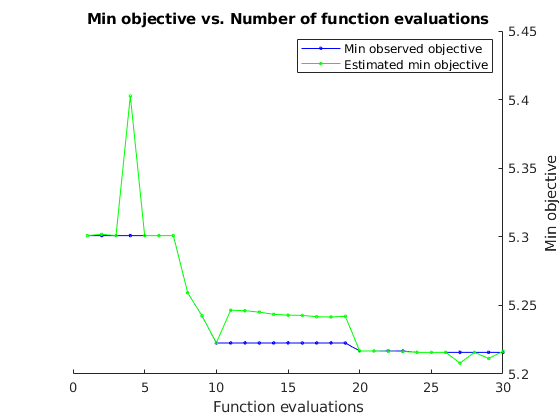

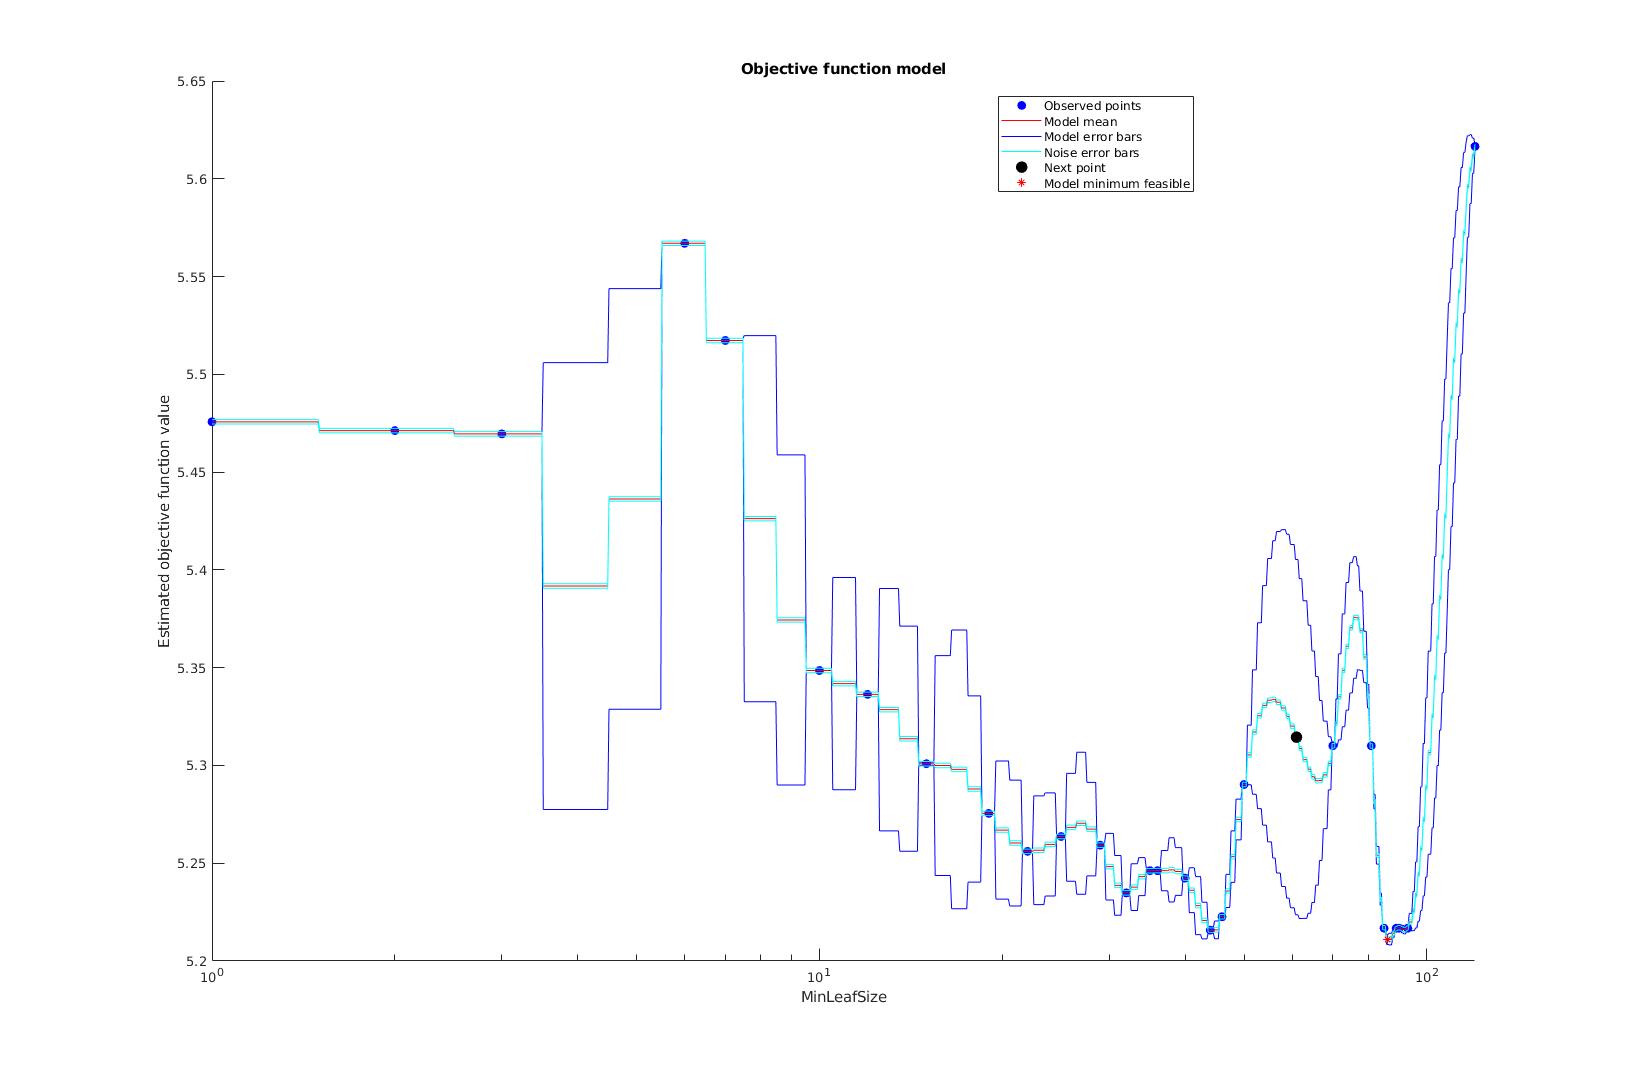


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 28.9044 seconds.
Total objective function evaluation time: 1.9951

Best observed feasible point:
    MinLeafSize
    ___________

        44     

Observed objective function value = 5.2158
Estimated objective function value = 5.2158
Function evaluation time = 0.037138

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        89     

Estimated objective function value = 5.2166
Estimated function evaluation time = 0.034198



dt =   RegressionTree
                         ResponseName: 'Y'
                CategoricalPredictors: []
                    ResponseTransform: 'none'
                      NumObservations: 240
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


% Set up parallel toolbox to use 4 CPU cores.
%parpool(4)
%paroptions = statset('UseParallel',true);

% Fit decision tree with hyperparameter optimization
dt = fitrtree(Xtrain', Ytrain', 'OptimizeHyperparameters', 'auto')

% Compute the predicted values using the trained decision tree and the test
% metabolomics set
dt_ypred = predict(dt, Xtest')

dt_ypred =    37.5698
   37.5698
   37.5698
   57.3206
   57.3206
   57.3206
   57.3206
   37.5698
   37.5698
   57.3206


% Compute the correlation between the test set and the predicted age
% values.
r_dt = corr(Ytest', dt_ypred)

r_dt = 0.6196

The decision trees don't outperform the neural networks. Let's try using ensemble methods next.

#### Random forests

Finally, let's train a random forest regression model with hyperparameter optimization.

|===================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |       5.021 |     0.61267 |       5.021 |       5.021 |      LSBoost |           11 |      0.71587 |           65 |


|    2 | Best   |      4.6605 |      2.9281 |      4.6605 |       4.689 |      LSBoost |           68 |      0.13036 |            9 |


|    3 | Accept |      4.9252 |      2.4346 |      4.6605 |       4.691 |          Bag |           71 |            - |            2 |


|    4 | Accept |      5.0119 |     0.37353 |      4.6605 |       4.673 |          Bag |           11 |            - |            2 |


|    5 | Accept |      4.7481 |     0.55869 |      4.6605 |      4.6607 |      LSBoost |           11 |      0.26084 |            9 |


|    6 | Accept |      5.0455 |      18.855 |      4.6605 |      4.6752 |      LSBoost |          464 |       0.7303 |            9 |


|    7 | Accept |      6.1421 |     0.45521 |      4.6605 |      4.6608 |      LSBoost |           11 |     0.086603 |            1 |


|    8 | Accept |      7.5492 |     0.41116 |      4.6605 |      4.6722 |      LSBoost |           11 |      0.01387 |            9 |


|    9 | Accept |      5.3306 |     0.26238 |      4.6605 |      4.6724 |      LSBoost |           11 |      0.15496 |           58 |


|   10 | Accept |      5.0708 |     0.29461 |      4.6605 |      4.6651 |          Bag |           11 |            - |           18 |


|   11 | Best   |      4.6496 |      5.8743 |      4.6496 |      4.6465 |      LSBoost |          146 |      0.25235 |           13 |


|   12 | Accept |      4.7236 |     0.67179 |      4.6496 |      4.6466 |      LSBoost |           27 |      0.32244 |           44 |


|   13 | Accept |      7.8183 |     0.37687 |      4.6496 |       4.649 |      LSBoost |           10 |     0.001013 |            9 |


|   14 | Accept |      5.4841 |     0.54401 |      4.6496 |       4.649 |      LSBoost |           14 |      0.98711 |            2 |


|   15 | Accept |      5.6294 |     0.18458 |      4.6496 |      4.6503 |          Bag |           10 |            - |          120 |


|   16 | Accept |       5.062 |      0.3726 |      4.6496 |        4.61 |      LSBoost |           10 |      0.18648 |           14 |


|   17 | Accept |      4.6616 |      1.2404 |      4.6496 |      4.5962 |      LSBoost |           34 |      0.30184 |           10 |


|   18 | Accept |      4.7909 |      1.7764 |      4.6496 |      4.6663 |      LSBoost |           49 |       0.2787 |           14 |


|   19 | Best   |      4.5862 |      5.3207 |      4.5862 |      4.5865 |      LSBoost |          137 |       0.2067 |           12 |


|   20 | Accept |      5.6269 |      2.8242 |      4.5862 |      4.6137 |      LSBoost |          222 |      0.11317 |          117 |


|===================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|   21 | Accept |      4.6523 |      15.844 |      4.5862 |      4.6288 |      LSBoost |          387 |      0.20408 |            8 |


|   22 | Accept |      4.7338 |      11.987 |      4.5862 |      4.6318 |      LSBoost |          324 |      0.26302 |           17 |


|   23 | Accept |      4.7901 |      2.8512 |      4.5862 |      4.6559 |      LSBoost |           69 |      0.24361 |            7 |


|   24 | Accept |      4.8224 |      0.3911 |      4.5862 |      4.6543 |      LSBoost |           11 |      0.46698 |           17 |


|   25 | Accept |      4.9026 |      11.729 |      4.5862 |      4.6733 |          Bag |          500 |            - |           10 |


|   26 | Accept |      5.6269 |      0.1938 |      4.5862 |      4.6725 |      LSBoost |           12 |       0.3884 |          118 |


|   27 | Accept |      5.2269 |     0.45866 |      4.5862 |      4.6708 |      LSBoost |           13 |      0.97815 |           26 |


|   28 | Accept |      4.8663 |     0.46259 |      4.5862 |      4.6684 |      LSBoost |           10 |      0.33757 |            8 |


|   29 | Accept |      4.9557 |     0.39515 |      4.5862 |       4.668 |          Bag |           10 |            - |            1 |


|   30 | Accept |      4.7113 |      18.558 |      4.5862 |       4.682 |      LSBoost |          433 |      0.26537 |           14 |


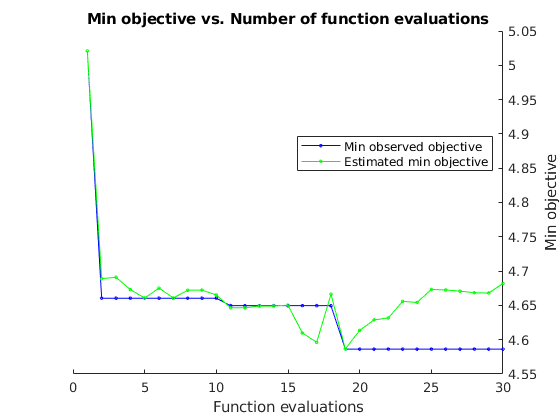


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 148.2022 seconds.
Total objective function evaluation time: 109.2418

Best observed feasible point:
    Method     NumLearningCycles    LearnRate    MinLeafSize
    _______    _________________    _________    ___________

    LSBoost           137            0.2067          12     

Observed objective function value = 4.5862
Estimated objective function value = 4.6953
Function evaluation time = 5.3207

Best estimated feasible point (according to models):
    Method     NumLearningCycles    LearnRate    MinLeafSize
    _______    _________________    _________    <

rf =   classreg.learning.regr.RegressionEnsemble
                         ResponseName: 'Y'
                CategoricalPredictors: []
                    ResponseTransform: 'none'
                      NumObservations: 240
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 146
                               Method: 'LSBoost'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: [146×1 double]
                   FitInfoDescription: {2×1 cell}
                       Regularization: []


  Properties, Methods


% Train a random forest model
rf = fitrensemble(Xtrain', Ytrain', 'OptimizeHyperparameters', 'auto')

% Compute the predicted values from random forests
rf_ypred = predict(rf, Xtest')

rf_ypred =    31.8361
   40.6983
   58.8475
   52.4562
   70.8259
   63.9647
   71.3148
   28.6076
   30.2296
   47.4069


% Compute the correlation between the random forest predictions and the
% test set
r_rf = corr(Ytest', rf_ypred)

r_rf = 0.8418

## Summary

From our regression analyses benchmarking neural networks against tree-based methods, we found that the shallow neural network predictions had the highest Pearson correlation with the age metabolomics dataset compared to decision trees and random forests.

### Built in MATLAB functions covered in this lesson

`fitlm:`                                Fit a linear regression model

`predict`:                             Compute a prediction from the trained model and the test dataset.

`corr:`                                  Compute the Pearson correlation between the predictive values and the test response.

`sequenceInputLayer:  `Stores the input dataset $X_{\textrm{train}}$ as a MATLAB object for the `trainNetwork` function.

`fullyConnectedLayer: `Creates a single hidden layer object for the` trainNetwork `function.

`dropoutLayer`:                   Drop out nodes in the neural network to prevent model overfitting.

`reluLayer:           `Performs a ReLU transformation for the activation function.

`regressionLayer:     `Output the regressed values from the neural net

`trainingOptions:     `Creates an object that specifies the neural network hyperparameters.

`trainNetwork:        `Trains a neural network.

`fitrtree`:                           Fit a decision tree

`fitrensemble`:                   Fit an ensemble model using boosting / bagging / random forests

`templateTree`:                   Return a default decision tree template

### List of custom functions

`trainTestSplit:      `Splits an input ($X$) and output ($Y$) dataset into a training $\left(X_{\textrm{train}} {,\;Y}_{\textrm{train}} \right)$ and testing $\left(X_{\textrm{test}} {,\;Y}_{\textrm{test}} \right)$dataset.